# **LAB SESSION 11**

## **Covarience.**

**Objective:** To get familiar with Covarience and its implementation in MATLAB

**Introduction:**

    **Covarience:**

    It is one of a family of statistical technique that is used to analyze the relationship between two random variables.

    There are three types of Corelation;

- +ve Covarience

- -ve Covarience

- 0 Covarience


$${\textrm{C}V}_{\textrm{XY}} =\frac{1}{N-1}\sum_{i=1}^N \left(X_i -\mathrm{X'}\right)\left(Y_i -\mathrm{Y'}\right)$$


%%CoVarience
clear all
clc
N = input('Enter the Number of Samples:\n     1.Scalar (e.g: 2)\n');
for i = 1:N
    %display('For Sample #',num2str(i))
    IP = input('\nEnter the Sample Data:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n');
    n = length(IP);
    M_IP(i) = sum(IP)/n;
    
    for j = 1:n
        V(i,j) = IP(j) - M_IP(i);
    end
    
end
for k = 1:n
    P(k) = V(1,k) * V(2,k);
end
sum_P = sum(P);
CV = sum_P/(N-1);

if     CV < 0
    disp('-ve Relation')
    
elseif CV > 0
    disp('+ve Relation')
    
elseif CV == 0
    disp('No Relation')
    
end

+ve Relation


**TASK # 1**

**Find the Correlation and tell the type of covarience.**

**Cigrattes (X) = 0 , 5 , 10 , 15**

**Lung Capacity (Y) = 45 , 42 , 33, 31**

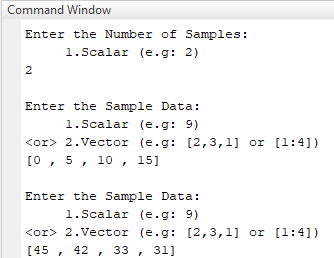

Results:

        CV = -127.5

        -`ve Relation`

**TASK # 2**

**Rising Hill anufacturing wishes to study the relationship between the # of Workers (X) and the # of Tables (Y). To do so 10 samples are obtained. Find the Covarience and tell the type of covarience.**

**X = 12 , 30 , 15 , 24 , 14 , 18 , 28 , 26 , 19 , 27**

**Y = 20 , 60 , 27, 50 , 21 , 30 , 61 , 54 , 32 , 57**

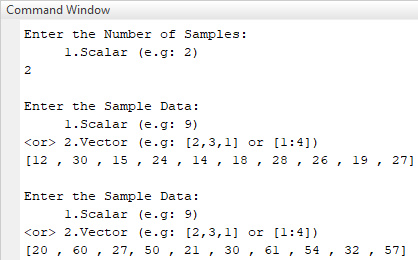

Results:

        CR = 962.4

        `+ve Relation`

**TASK # 3**

**Following tavle give the Weight (X) and Waist Size (Y) of 10 friends. Find the Correlation and tell the type of correlation.**

**Weight_kg (X) = 87 , 65 , 52 , 94 , 87 , 79 , 59 , 64 , 45 , 77**

**WaistSize_cm (Y) = 101 , 71 , 62 , 113 , 88 , 87 , 71 , 83 , 58 , 85**

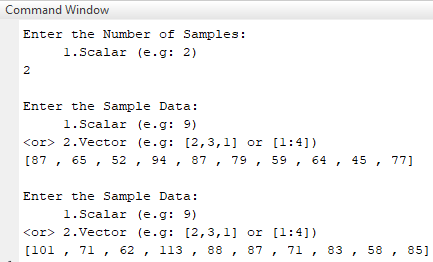

Results:

        CR = 2345.9

        `+ve Relation`